% wwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwww
% Beginning Terminal guidance STK Matlab
% wwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwwww

clear all
close all
clc

global STK_version;


## Inputs


STK_version = 'STK11.Application';

target = spacecraft(6371 + 1200,0,0,88,24,260);

chaser = spacecraft(6371 + 1200.05,0,0,88.01,24.02,261);

time = 60*60*0.5 %for 1 hour rendez-vous

time = 1800

## Genetic Algorithm optimisation

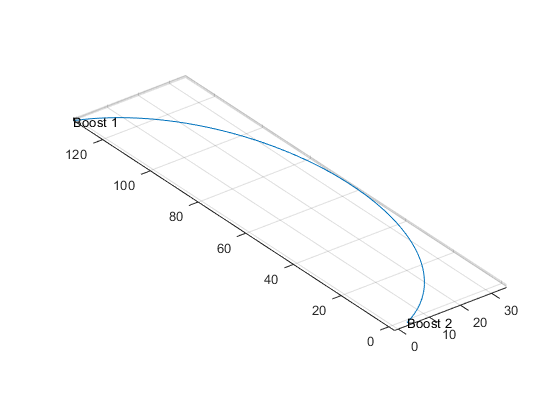

%initialisation
[boost, distance_end,distance_begin] = STK_simulation(target,chaser,time);


disp("initial distance arrival")

initial distance arrival


disp(distance_end);

        3729




disp("initial boost")

initial boost


disp(boost);

    0.0723   -0.0289   -0.0001




%meta parameters
memberAmount = 10;
generationAmount = 50;
dif = 40; %sensibility

%% GeneticAlgoritm
    
% Starting population

population(1).x = boost(1,1);
population(1).y = boost(1,2);
population(1).z = boost(1,3);
population(1).distance = distance_end;

for i = 2:1:memberAmount
    %todo implement random
    population(i).x = boost(1,1)*(rand(1)/dif + (1-0.5*(1/dif)));
    population(i).y = boost(1,2)*(rand(1)/dif + (1-0.5*(1/dif)));
    population(i).z = boost(1,3)*(rand(1)/dif + (1-0.5*(1/dif)));
    population(i).distance = distance_end;
end

% Process selection best deltaV
for j = 1:1:generationAmount

    %disp('Generation')
    %disp(j)

    for i = 1:1:memberAmount

    % Calculation the end position for each solution
        
        DV =  [population(i).x population(i).y population(i).z];
        [boost_ge, distance_end_ge] = GENalg_STK_simulation(DV,target,chaser,time);

        % get the error
        error = distance_end_ge;
        population(i).distance = distance_end_ge;

        % give marks on best angles solutions
        population(i).fitness = 1/error;

    end

    % Select the best solution angles
    [bestfitness, indexBestSolution] = max([population.fitness]);
    BestSolution = population(indexBestSolution);

    % Create the table of maks "fitness"
    fitness(1,j) = bestfitness;

    %get improvement percentage
    improvement = BestSolution.distance/population(1).distance;
    
    % Create new solutions from the best one of last generation
    population(1) = BestSolution;
  
    %disp data useful
    X = ['Generation ', num2str(j) ,' , best distance :', num2str(BestSolution.distance)];
    disp(X)
    
    %define new dif rate
    dif = dif/improvement;
    
    for i = 2:1:memberAmount-1
        population(i).x = BestSolution.x*(rand(1)/dif + (1-0.5*(1/dif)));
        population(i).y = BestSolution.y*(rand(1)/dif + (1-0.5*(1/dif)));
        population(i).z = BestSolution.z*(rand(1)/dif + (1-0.5*(1/dif)));
    end
    
    
    
end

Generation 1 , best distance :1555
Generation 2 , best distance :1119
Generation 3 , best distance :984
Generation 4 , best distance :906
Generation 5 , best distance :775
Generation 6 , best distance :746
Generation 7 , best distance :582
Generation 8 , best distance :535
Generation 9 , best distance :498
Generation 10 , best distance :434
Generation 11 , best distance :358
Generation 12 , best distance :300
Generation 13 , best distance :300
Generation 14 , best distance :266
Generation 15 , best distance :236
Generation 16 , best distance :225
Generation 17 , best distance :194
Generation 18 , best distance :175
Generation 19 , best distance :172
Generation 20 , best distance :156
Generation 21 , best distance :136
Generation 22 , best distance :114
Generation 23 , best distance :95
Generation 24 , best distance :91
Generation 25 , best distance :85
Generation 26 , best distance :78
Generation 27 , best distance :72
Generation 28 , best distance :72
Generation 29 , best distance :68



Best_boost = [BestSolution.x BestSolution.y BestSolution.z]

Best_boost =     0.0718   -0.0299   -0.0001


Best_distance = BestSolution.distance

Best_distance = 11


[boost, distance_end] = GENalg_STK_simulation(Best_boost,target,chaser,time);

%save('Best_boost.mat');
